# Gaussian convoluted firing rate

## Testing on 5 Hz spike train

alpha = 9.9950

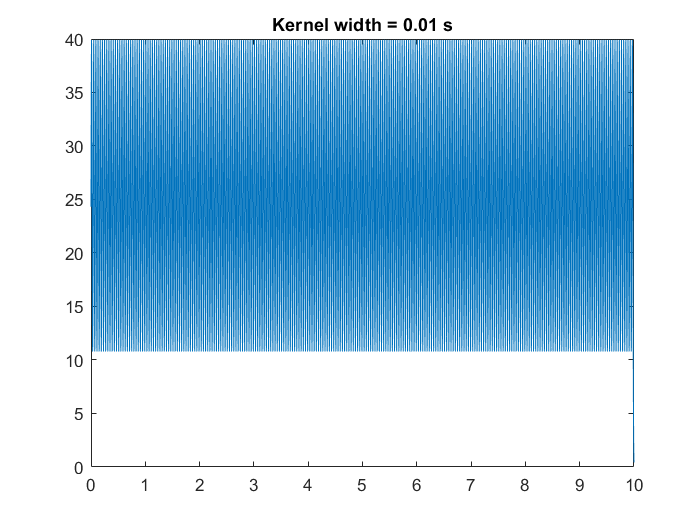

alpha = 7.7388

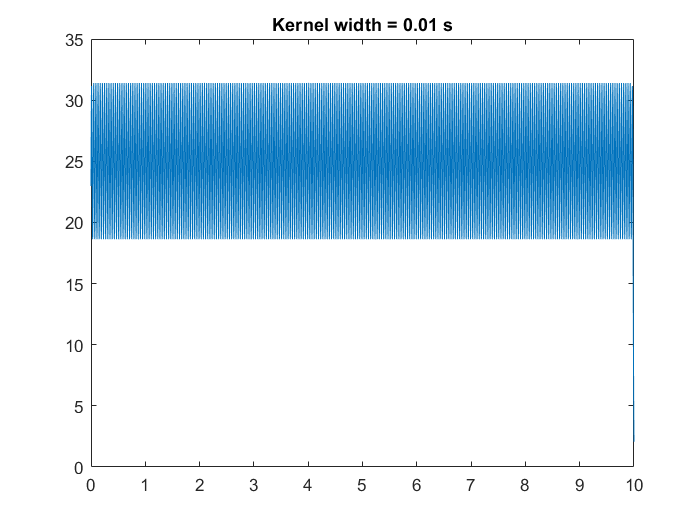

alpha = 5.9918

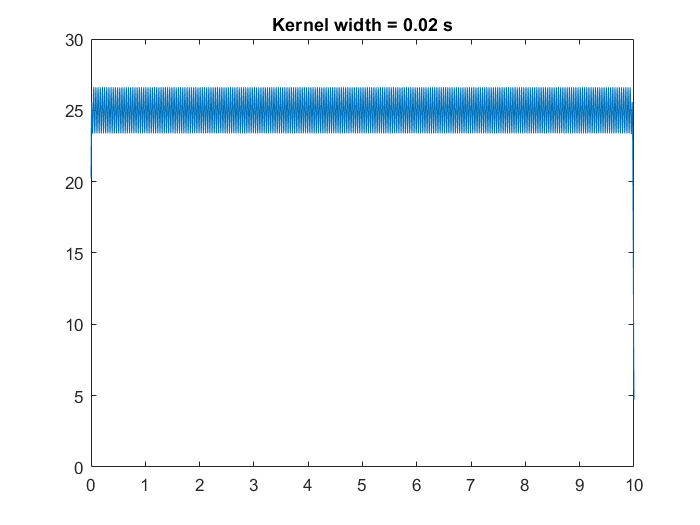

alpha = 4.6393

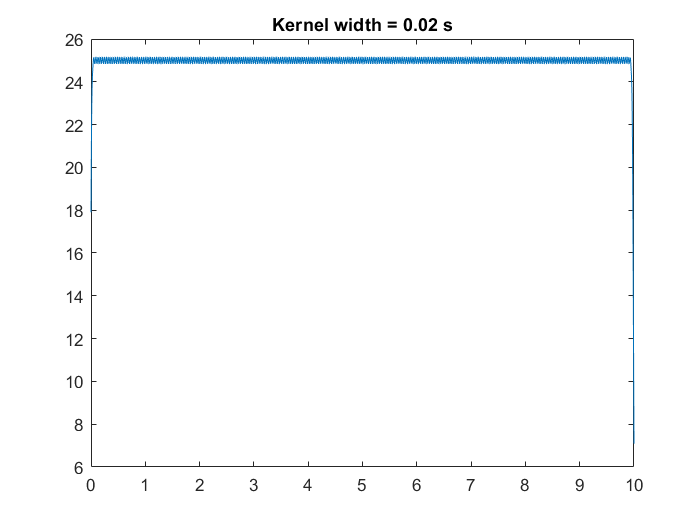

alpha = 3.5920

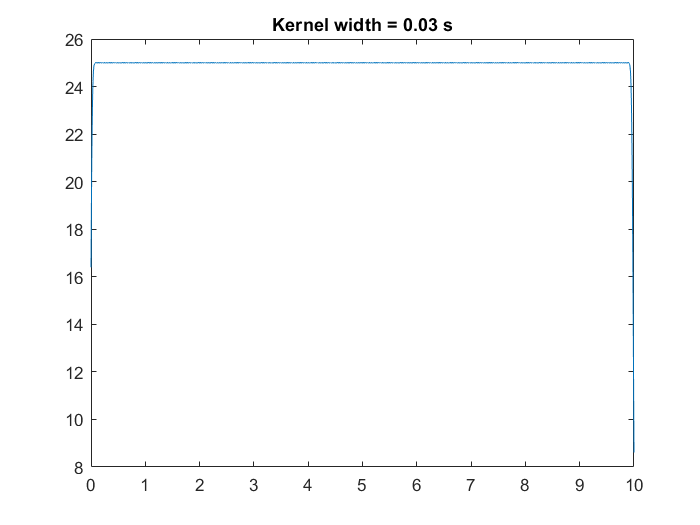

alpha = 2.7812

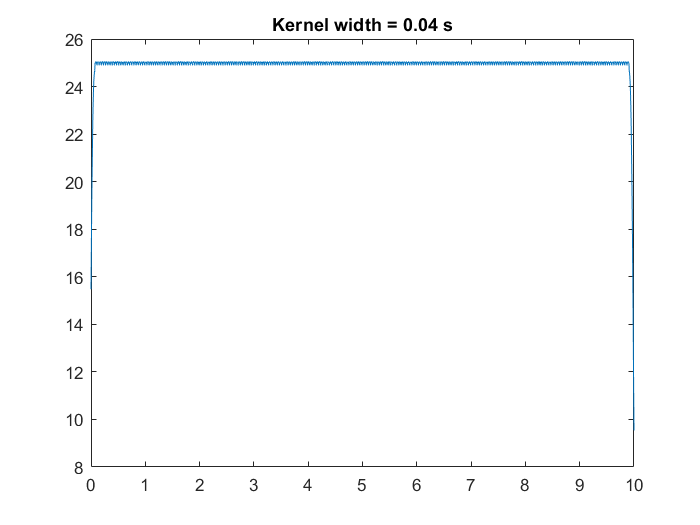

alpha = 2.1534

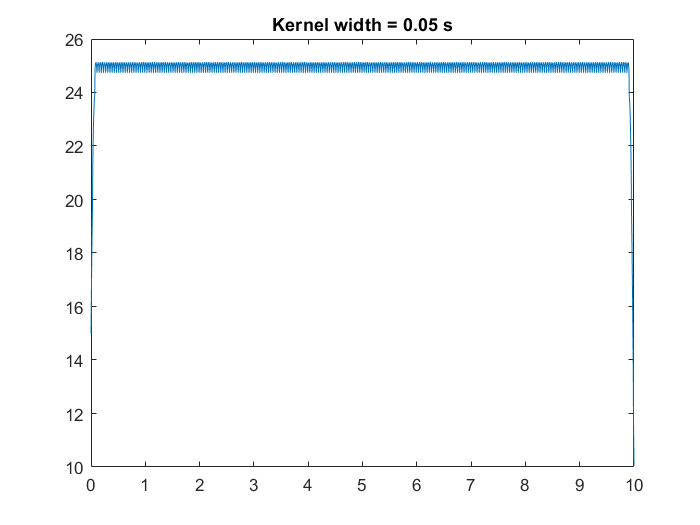

alpha = 1.6673

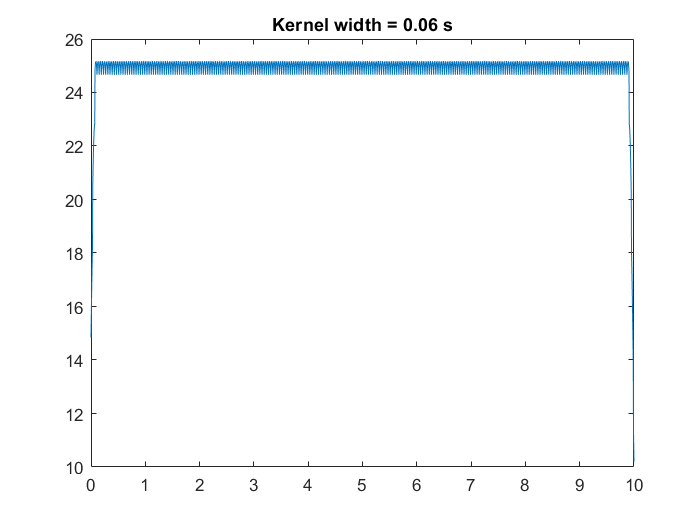

alpha = 1.2909

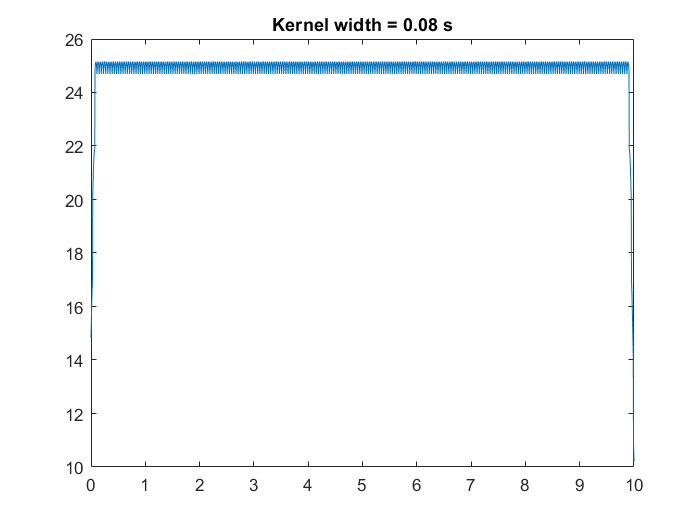

alpha = 0.9995

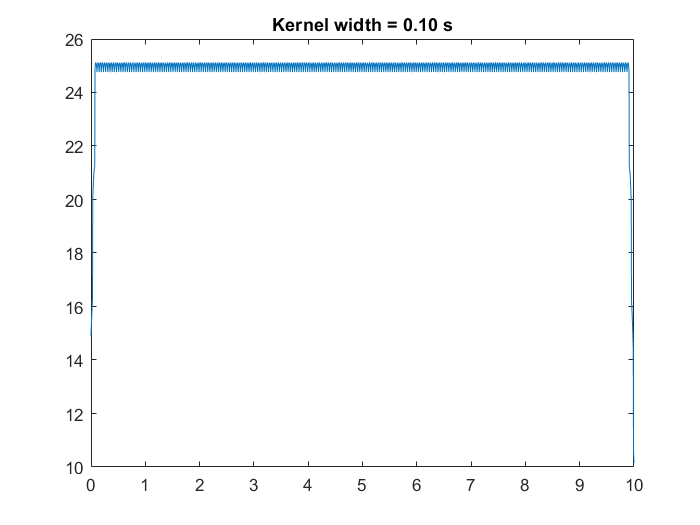

fs = 10000;
t=0:1/fs:10;
freq=25;
x= sin(2*pi*freq*t);
raster = zeros(1,length(t));
figure;
plot(t,x);
% ind = find(x==1);
[pks,ind] = findpeaks(x);
raster(ind) = 1;
hold on;
plot(ind/fs,x(ind),'|');

L = fs/5;
w = logspace(-2,-1,10);
% w = linspace(0.01,100,10);


for i  = 1:length(w)
    alpha = ((L-1)/(2*w(i)*fs))
    gw = gausswin(round(L), alpha);
%     gcfr = fs*filtfilt(gw, sum(gw), raster);
    gcfr = (fs/sum(gw))*conv(raster,gw, 'same');
    figure;
    plot(t,gcfr);   
    title(sprintf('Kernel width = %0.2f s', w(i)));
end

## GCFR using convolution

gcfr_conv = (fs/sum(gw))*conv(raster,gw, 'same');
figure;
plot(gcfr_conv); hold on; plot(x)